# Ćwiczenie A1

## Modelowanie i symulacja w programie MATLAB cz.1

Mateusz Wójcik, 10.10.2024

Zajęcia mające na celu zapoznanie się z podstawami obsługiwania się interfejsem MATLABa (import i wizualizacja danych) oraz tworzenia wektorów i tablic oraz dokonywania obliczeń na danych. Zajęcia polegają na zapoznaniu się z konspektem oraz wykonaniu odpowiednich poleceń.

clear, clc

## Zadanie a 

a = 23
b = 5

b = 5

c = round(a/b)

c = 5

d = mod(a,b)

d = 3

## Zadanie b

v = [0 5 0 4 0]'

v =      0
     5
     0
     4
     0


## Zadanie c

std_r2 = 5;
mean_r2 = 3;
R2 = std_r2*randn(5,3) + mean_r2

R2 =    11.0173    2.2203   -3.2534
    9.1734    4.3803   -1.7398
    1.8519    1.6942   -0.7055
   -4.5308    5.2171    0.4609
    0.7769    4.9595    1.3971


## Zadanie d

R2_V = [R2 v]

R2_V =    11.0173    2.2203   -3.2534         0
    9.1734    4.3803   -1.7398    5.0000
    1.8519    1.6942   -0.7055         0
   -4.5308    5.2171    0.4609    4.0000
    0.7769    4.9595    1.3971         0


## Zadanie e

x = 0:pi/10:2*pi

x =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832


y = sin(x)

y =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000


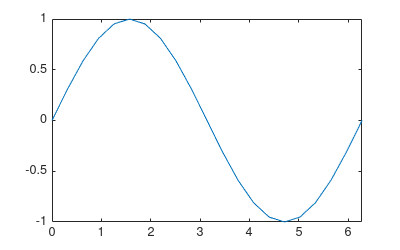

plot(x,y)

set(gcf,'position',[0,0,400,250]);


## Zadanie f

Matematycznie średnia powinna wynieść 0, natomiast widać, że z powodu błędów spowodowanych reprezentacją cyfrową liczb otrzymaliśmy naprawdę mały wyraz rzędu 10^-17.

mean_y = mean(y)

mean_y = -2.4880e-17

## Zadanie g

A = [[1 2 3];
    [-1 1 4];
    [-1 -2 -3]];
b = [5 1 -5]';

Rząd macierzy wynosi $2 < 3$, zatem układ jest nieoznaczony:

rank(A)

ans = 2

Co potwierdza działanie przeprowadzone w Matlabie:

sol = inv(A)\b

sol =    NaN
   NaN
   NaN


## Zadanie h

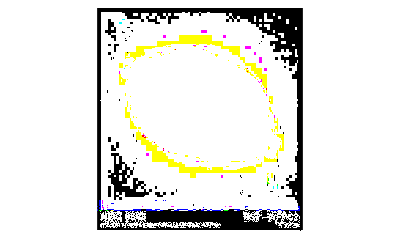

load("cwiczenie_A1_dane/exampledata.mat")
imshow(RGB)
set(gcf,'position',[0,0,400,250]);

[m,n,o] = size(RGB);
R = reshape(RGB(:,:,1), [1, m*n]);
G = reshape(RGB(:,:,2), [1, m*n]);
B = reshape(RGB(:,:,3)',[1, m*n]);
RGB = [R; G; B]

RGB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


A_h = [[0.299 0.587 0.114];[-0.169 -0.331 0.5];[0.5 -0.419 -0.081]]

A_h =     0.2990    0.5870    0.1140
   -0.1690   -0.3310    0.5000
    0.5000   -0.4190   -0.0810


b_h = [0 128 128]'

b_h =      0
   128
   128


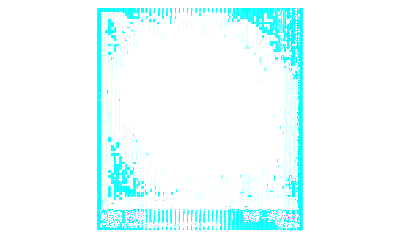

YCbCr = b_h + A_h * RGB;
Y = reshape(YCbCr(1,:), [m,n]);
Cb = reshape(YCbCr(2,:), [m,n]);
Cr = reshape(YCbCr(3,:), [m,n]);

YCbCr = reshape([Y Cb Cr], [m,n,3]);
imshow(YCbCr)
set(gcf,'position',[0,0,400,250]);

## Zadanie i

a = pi

a = 3.1416

b = ones(1,1,'uint8')

b = uint8
1

Bez konwersji

a+b

ans = uint8
4

Z konwersją na double

a+double(b)

ans = 4.1416

## Zadanie j

base = ['a' 'b' 'c' 'd' 'e' 'f' 'g'];
perm = randi(6,[10,1])

perm =      4
     2
     5
     2
     4
     5
     6
     6
     4
     1


result = arrayfun(@(x) base(x), perm)

result = 10×1 char array
    'd'
    'b'
    'e'
    'b'
    'd'
    'e'
    'f'
    'f'
    'd'
    'a'


## Wnioski

Na laboratorium zapoznano się z podstawowymi zagadnieniami korzystania z Matlaba. Podczas zajęć zapoznano się z metodami tworzenia zmiennych oraz podstawowymi operacjami matematycznymi na nich. Następnym krokiem było poznanie możliwości tworzenia i wykonywania operacji na wektorach oraz macierzach, stosując m.in. konkatenacje wektora i macierzy. Nauczono się również rozwiązywać się układy równań za pomoca reprezentacji macierzowej w Matlabie. Następnie stworzono i wyświetlono wykres funkcji matematycznej sinus. Kolejnym etapem było uzycie podstawowej metody do przetwarzania obrazu przechodzą z obrazu zapisanego jako RGB na reprezentacje YCbCr. W zadaniu i porównano różnicę między dokładnością różnych typów zmiennych i błąd jaki to za sobą pociąga. W ostatnim zadaniu zapoznano się z możliwościami manipulacji tablicą o innym typie niż liczbowy, tworząc pseudolosowy wektor liter.